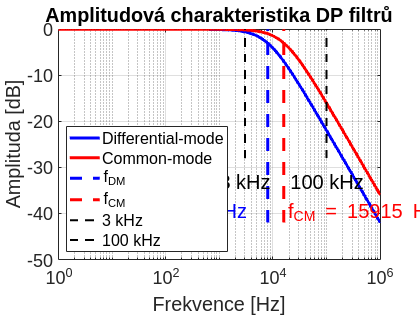

% Definice parametrů filtru
R_CM = 10e3; % Odpor R_CM v Ohmech
C_CM = 1e-9; % Kapacita C_CM v Faradech
C_DM = 1e-9; % Kapacita C_DM v Faradech

% Výpočet zlomových frekvencí
f_CM = 1 / (2 * pi * R_CM * C_CM);
f_DM = 1 / (2 * pi * 2 * R_CM * C_DM); % R_DM = 2 * R_CM

% Vytvoření vektoru frekvencí
f = logspace(0, 6, 500); % Frekvence od 1 Hz do 1 MHz

% Výpočet přenosových funkcí
H_CM = 1 ./ (1 + 1i * f / f_CM);
H_DM = 1 ./ (1 + 1i * f / f_DM);

% Výpočet magnitud a převod na dB
mag_CM = abs(H_CM);
mag_DM = abs(H_DM);
mag_CM_db = 20 * log10(mag_CM);
mag_DM_db = 20 * log10(mag_DM);

% Vykreslení frekvenční charakteristiky
figure;
semilogx(f, mag_DM_db, 'b', 'LineWidth', 3);
hold on;
semilogx(f, mag_CM_db, 'r', 'LineWidth', 3);

title('Amplitudová charakteristika DP filtrů','FontSize', 24);
xlabel('Frekvence [Hz]','FontSize', 20);
ylabel('Amplituda [dB]','FontSize', 20);
grid on;

% Zobrazení zlomových frekvencí v grafu
semilogx([f_DM, f_DM], [min([mag_DM_db,mag_CM_db]), max([mag_DM_db,mag_CM_db])], 'b--', 'LineWidth', 3);
semilogx([f_CM, f_CM], [min([mag_DM_db,mag_CM_db]), max([mag_DM_db,mag_CM_db])], 'r--', 'LineWidth', 3);


% Umístění popisků frekvencí mimo čáry
y_offset = (max([mag_DM_db,mag_CM_db]) - min([mag_DM_db,mag_CM_db])) * 0.1; % 10% odstup

% Přidání textu a čar pro 3 kHz a 100 kHz
f_3k = 3e3;
f_100k = 100e3;

% Najdeme nejbližší index pro 3kHz a 100kHz ve vektoru f
[~, index_3k] = min(abs(f - f_3k));
[~, index_100k] = min(abs(f - f_100k));

% Získání hodnot magnitudy v dB pro 3kHz a 100kHz
mag_DM_3k_db = mag_DM_db(index_3k);
mag_CM_3k_db = mag_CM_db(index_3k);
mag_DM_100k_db = mag_DM_db(index_100k);
mag_CM_100k_db = mag_CM_db(index_100k);

% Nastavení limitu pro přerušované čáry na -25 dB
limit_db = -28;

% Přidání přerušovaných čar pro 3 kHz a 100 kHz, omezené na -25 dB
semilogx([f_3k, f_3k], [limit_db, 0], 'k--', 'LineWidth', 2);
semilogx([f_100k, f_100k], [limit_db, 0], 'k--', 'LineWidth', 2);

% Legenda a popisky frekvencí
legend('Differential-mode', 'Common-mode', 'f_{DM}', 'f_{CM}','3 kHz','100 kHz', 'Location', 'SouthWest','FontSize', 16);


% Popisky pro 3 kHz a 100 kHz
text(f_3k, limit_db - 5, '3 kHz', 'HorizontalAlignment', 'center', 'Color', 'k', 'FontSize', 20);
text(f_100k, limit_db - 5, '100 kHz', 'HorizontalAlignment', 'center', 'Color', 'k', 'FontSize', 20);

text(f_DM * 1.1, max([mag_DM_db,mag_CM_db]) -40, ['f_{DM} = ' num2str(round(f_DM)) ' Hz  '], 'HorizontalAlignment', 'right', 'Color', 'b', 'FontSize', 20);
text(f_CM * 1.1, max([mag_DM_db,mag_CM_db]) -40, ['f_{CM} = ' num2str(round(f_CM)) ' Hz'], 'HorizontalAlignment', 'left', 'Color', 'r', 'FontSize', 20); % Posunuto níže

ax = gca;

% Set the FontSize property for the x and y axes
ax.XAxis.FontSize = 18;  % Example: 14 points
ax.YAxis.FontSize = 18;  % Example: 14 points

% Alternatively, you can set it for both at once:
ax.FontSize = 18; % This will affect XAxis, YAxis, and ZAxis if present.

% If you have a specific axes handle (e.g., from creating subplots):
% ax(1).XAxis.FontSize = 12; % For the first subplot
% ax(2).YAxis.FontSize = 16; % For the second subplot

hold off;


% Tisk zlomových frekvencí
fprintf('Zlomová frekvence f_DM = %.2f Hz\n', f_DM);

Zlomová frekvence f_DM = 7957.75 Hz


fprintf('Zlomová frekvence f_CM = %.2f Hz\n', f_CM);

Zlomová frekvence f_CM = 15915.49 Hz
